clear all
clf
format shortg



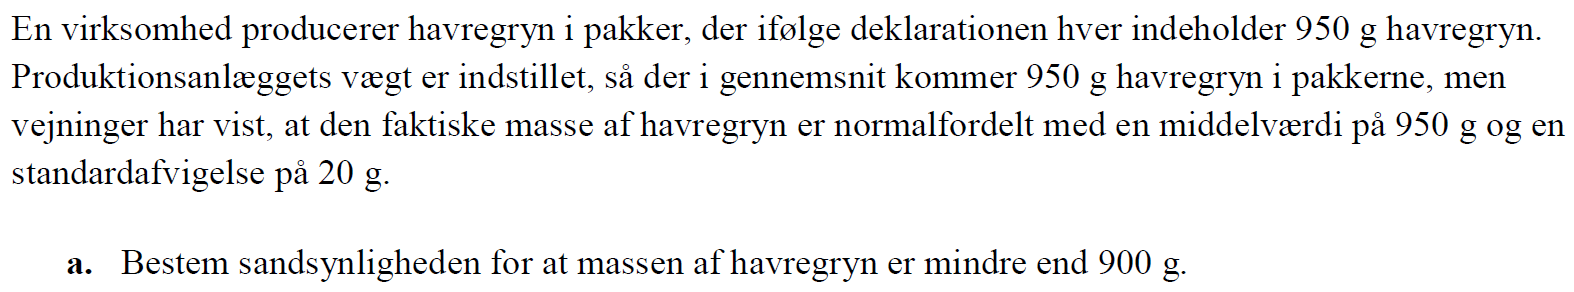

mu = 950
std = 20
P_mindre_900 = normcdf(900,mu,std)
% normcdf()% ,mu, std)


b. Bestem sandsynligheden for at massen af havregryn ligger i intervallet fra 900 g til 1010 g.

P_mindre_1010 = normcdf(1010,mu,std)
P_mindre_1010 - P_mindre_900


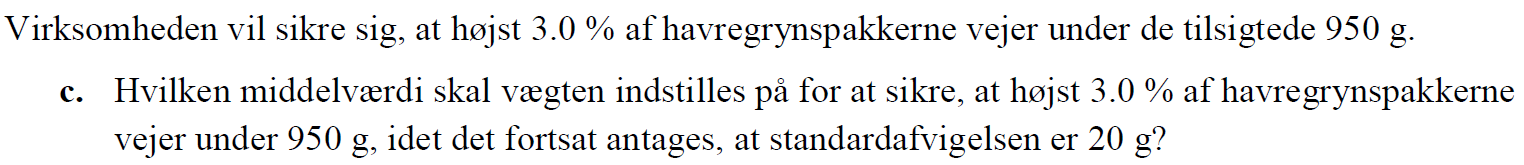

z_0 = norminv(0.03)
mu0 = mu - z_0*std

Vægten skal således vise

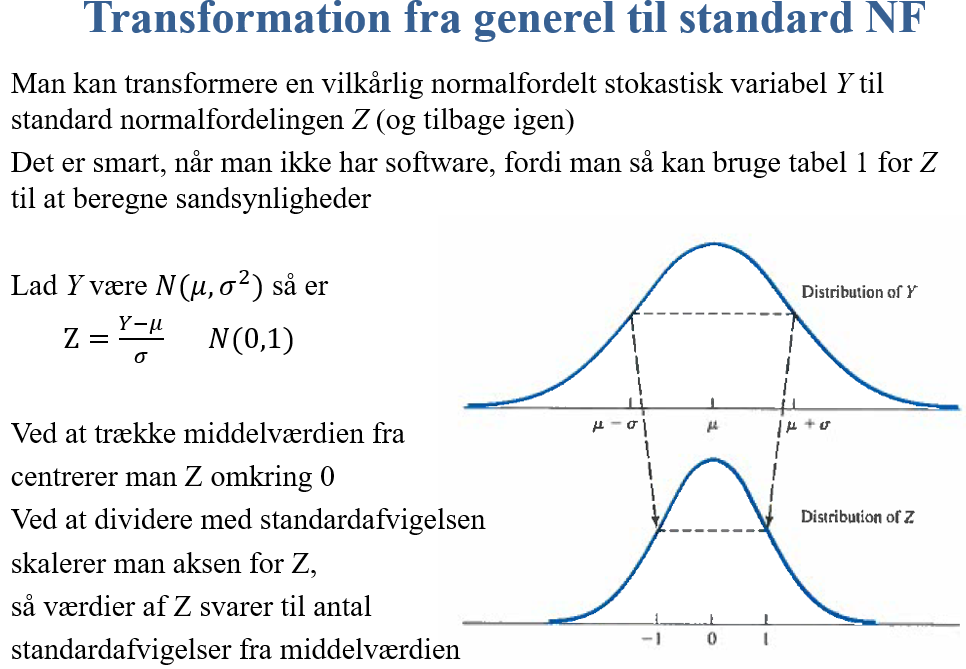

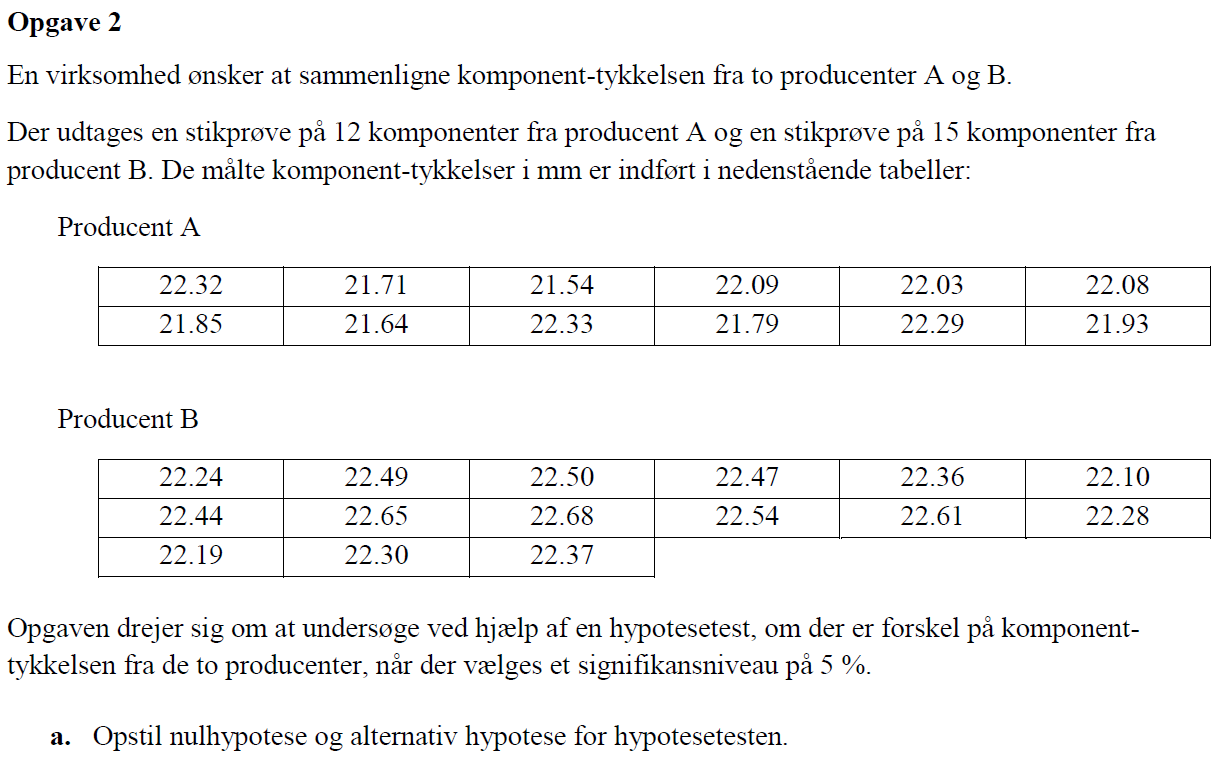

clear all
clf
format shortg
data = xlsread("Statestik\Eksamens sæt\21F\Data_M4STI1_2021F.xlsx");

% nr = data(:,1);


$$H_0:\ \mu_A = \mu_B \\
H_a :\ \mu_A \neq \mu_B \\$$


delta_0 = 0

b. Opstil en formel for teststørrelsen (teststatistikken), og angiv hvilken fordeling den følger.

Der benyttes en t-fordeling da variansen findes med stikprøverne.

Her har vi to stik prøver der er uafhængige således finder vi test størrelsen med formlen

c. Bestem det kritiske område for testen.

n_A = 12;%length(A)
n_B = 15;%length(B)
df = n_A + n_B - 2
t_c = tinv(1 - 0.025, df)

Vi forkaster nulhypotesen, hvis teststørrelsen t0 er større end 2.0595 eller mindre end -2.0595.

d. Beregn teststørrelsens (teststatistikkens) værdi, idet nødvendige mellemregninger medtages.

A = data(1:n_A,2);
B = data(n_A+1:n_A + n_B,2);


y_bar_B = mean(B)
s_B = std(B)
var_B = var(B)

% Den puljede varians var_p er et vægtet gennemsnit af de to stikprøvers varianser:
s_p = sqrt( ( (n_A -1) * s_A^2 + (n_B -1) * s_B^2 ) / (n_A + n_B - 2) )

%test størrelsen findes
t_0 = (y_bar_A - y_bar_B - delta_0) / (s_p * sqrt(1/n_A + 1/n_B))



e. Konkluder på hypotesetesten.

Vi undersøger om voresteststørrelse er mindre end den kritiske værdi.

abs(t_0) < t_c

Da den er størrer forkastes $H_0$ hypotesen og vi må således konkludere at der er forskel på tykkelserne.

f. Hvilke antagelser er der foretaget for at udføre hypotesetesten?

Er disse antagelser rimelige? I vurderingen af data fra de to producenter skal der indgå normalfordelingsplot og f.eks. Bartlett’s test eller boksplot.

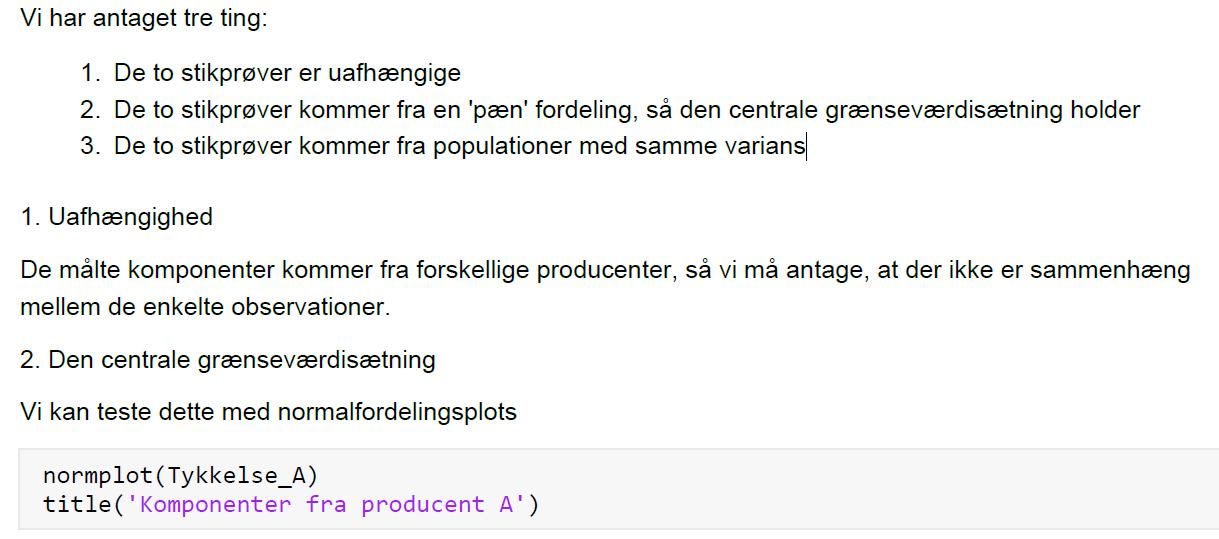

figure(1)
normplot(A)

figure(2)
normplot(B)

Data'ene ser ud til at komme fra en pæn fordeling.

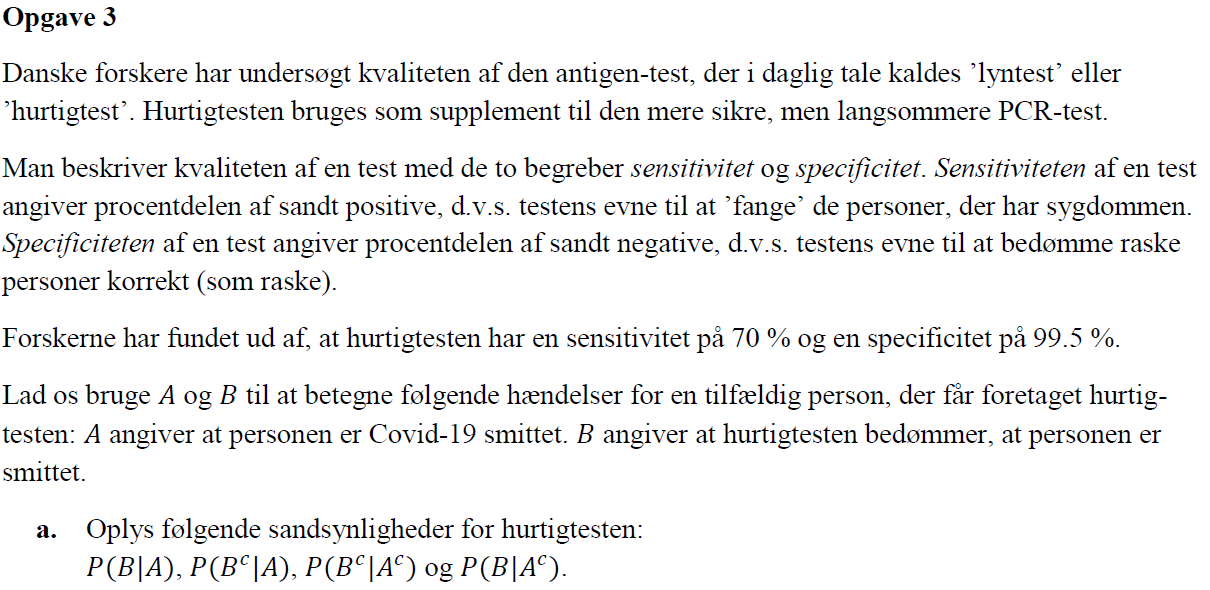

% 99,5% korrekt smittede
% 70% korrekt raske

% A = smittet
% B = viser smittet

P_B_giv_A = 0.70 % korrekt possitiv
P_Bc_giv_A = 1 - P_B_giv_A %falsk negativ
P_Bc_giv_Ac = 0.995 % korrekt negativ
P_B_giv_Ac = 1 - P_Bc_giv_Ac % falsk positiv

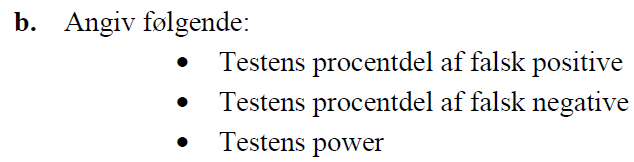

Falsk positiv er 0,5% af testene

Falsk negative er 30% af testene

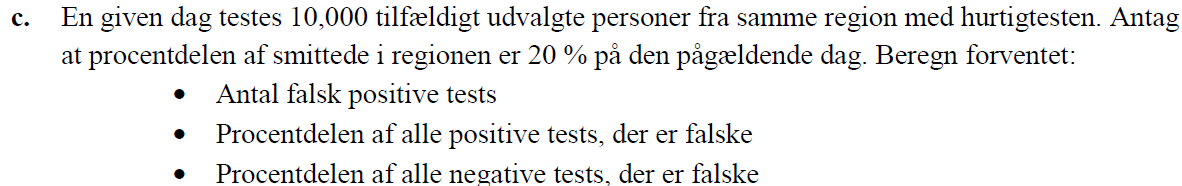

tot = 10000;
smittede = tot * 0.2
ikke_smittede = tot * 0.8

falsk_positiv = P_B_giv_Ac * ikke_smittede

n_falsk_positive = tot * (1 - 0.2) * P_B_giv_Ac % n_falsk_positive = 40

falsk_negativ = P_Bc_giv_A * smittede

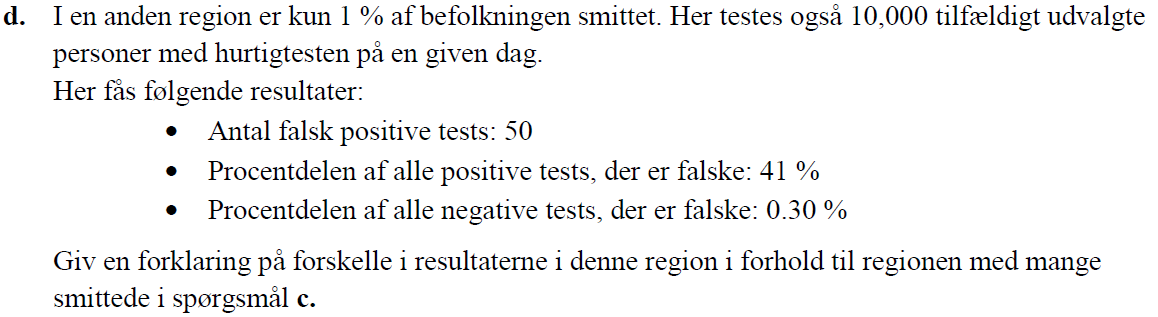

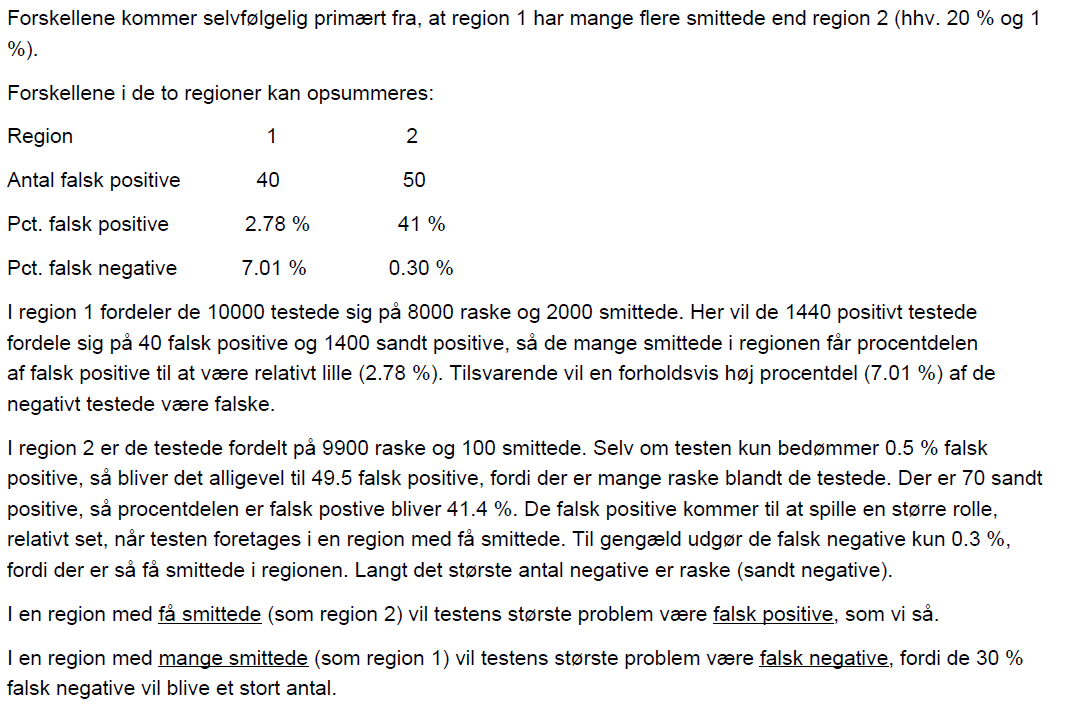

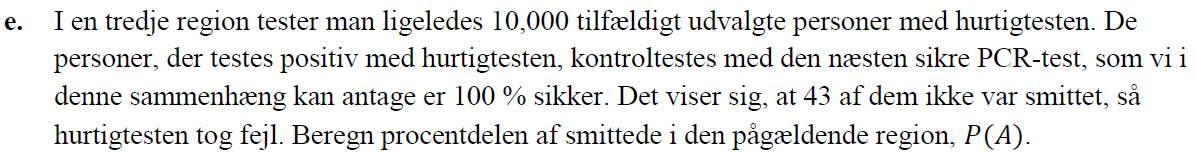

n_falsk_positive = 43
P_A = 1 - n_falsk_positive / (tot * P_B_giv_Ac)

14% er smittet.

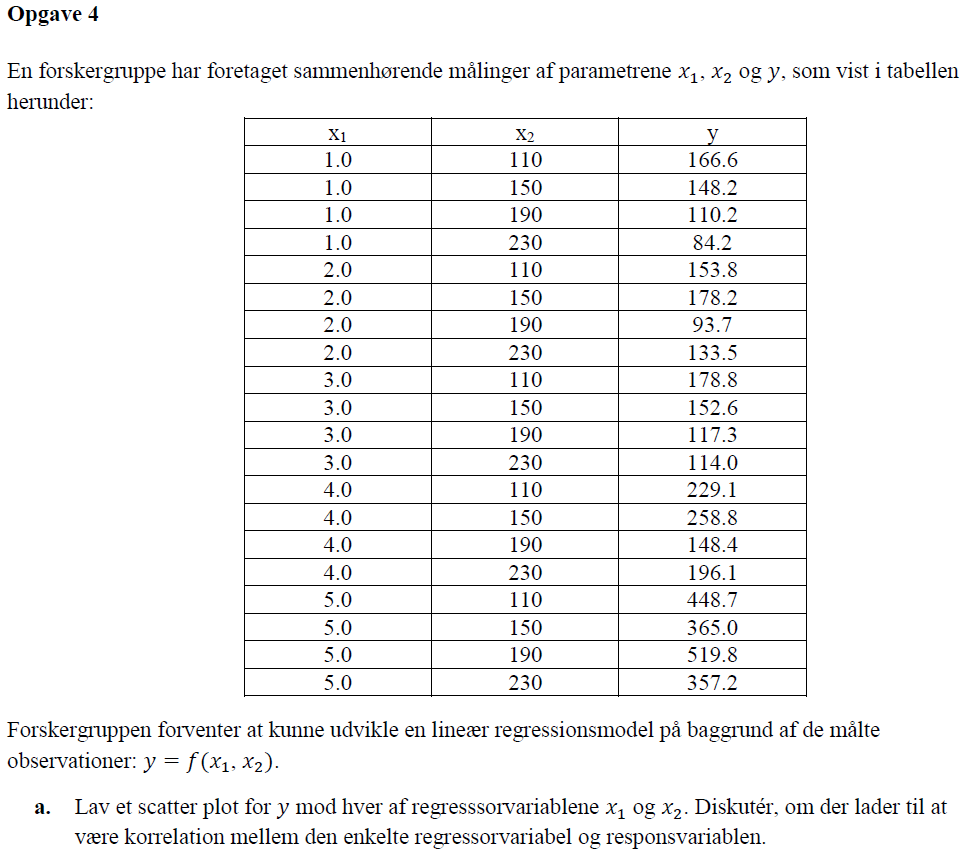

clear all
clf
format shortg
data = xlsread("Statestik\Eksamens sæt\21F\Data_M4STI1_2021F.xlsx");
x1 = data(1:20, 5);
x2 = data(1:20, 6);
y = data(1:20, 7);

figure(1)
scatter(x1, y, 'filled', DisplayName='x1 data')
lsline
xlabel('x1')
ylabel('y')
grid('minor')
legend('Location','best')

figure(2)
scatter(x2, y, 'filled', DisplayName='x2 data')
lsline
xlabel('x2')
ylabel('y')
grid('minor')
legend('Location','best')

for x1 er ser der mere ud til at være en expontiel tendens, den lineær model kunne måske passe på de første data punkter

for x2 ser målingerne ud til at være rime tilfældighed måske med en lille tendens til en negativ hældning.

b. Lav en multipel lineær regressionsmodel, der beskriver y som funktion af 𝑥1 og 𝑥2. Skriv funktionsudtrykket op.

mdl = fitlm([x1, x2], y)

Vi får nu funktionen


$$f(x_1, x_2) = 94,094 + 65,905 \cdot x_1 - 0,4947 \cdot x_2$$


c. Forklar vha. regressionsanalysens statistikker (f.eks. R-squared, F og p-value), om modellen beskriver observationerne godt.

Vi får en R værdi der er et godt stykke under 0,9 hvilket betyder at modellen passer dårligt. yderliger ses det at p værdierne er høje både for $b_0$ og $b_2$ disse værdier er således ikke ikke inden for sicnificant nivuet som formodes til 5%

mdl2 = fitlm([x1, x2], y, 'y ~ x1 + x2 + x1:x2')

Dette gør ikke modellen bedre.

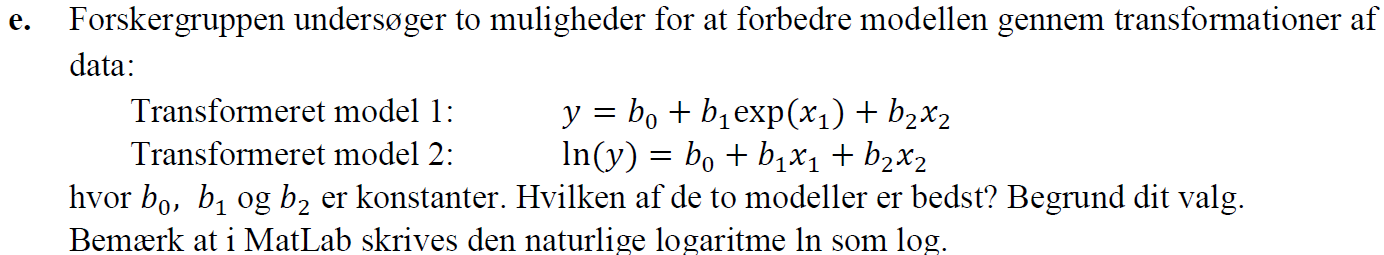

exp_x1 = exp(x1);
mdl3 = fitlm([exp_x1, x2], y)
ln_y = log(y);
mdl4 = fitlm([x1, x2], ln_y)

Her ser det ud til at model 1 passer bedst da den har den bedste R - værdi.

lev = mdl3.Diagnostics.Leverage; %løfte punkter %'unormale' i x-retningen
rst = mdl3.Residuals.Studentized; % Outlier punkter "unormale" værdier i y-retningen. abs(rst) skal gerne være mindre end 3


c = 2; %antal regressor variable
n = length(rst); %antalt observationer
lev_limit = 2 * (c +1 )/ n
find(lev > lev_limit)
find(abs(rst) > 3)

Der findes ingen outliers.

nr = (1:length(y))';
disp(table(nr, x1, x2, y, lev, rst))


b. Lav en multipel lineær regressionsmodel, der beskriver y som funktion af 𝑥1 og 𝑥2. Skriv funktionsudtrykket op.

c. Forklar vha. regressionsanalysens statistikker (f.eks. R-squared, F og p-value), om modellen beskriver observationerne godt.